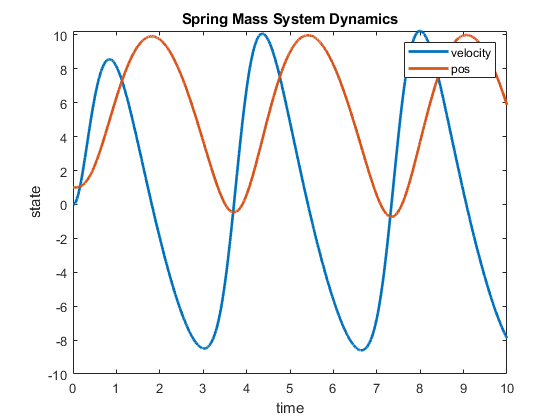

clc
clear
close all

tfinal = 10; dt = 0.001; % simulation parameters

%system parameters
k = 1; m = 1; b = 0.1;
A_sys = [0 1;-k/m 0]; B_sys = [0; 1/m]; 
A_PHS = [0 -1/m;k 0]; B_PHS = [1; 0];

% initial condition
x0 = [1;0]; x = x0; t = 0; H_phs = 0; 
p0 = m*x(2); p = p0; xm0 = x(1); xm = xm0;
phs0 = [p0;xm0]; phs = phs0;
Em0 = p0^2/(2*m); Em_phs = Em0; Em_x = Em0;
Ek0 = k*xm0^2/2; Ek_phs = Ek0; Ek_x = Ek0;
Er_phs = 0; Er_x = 0;
 
% Control parameters
x_des = 10; lambda = -1;
Q = [100 0;0 1];
R = 1;
g = lqr(A_sys,B_sys,Q,R);

% initialize memory
X = []; PHS = []; T = []; 
EM_PHS = []; EK_phs = [];
EM_X = []; EK_X = [];

while (t <= tfinal)
    T = [T,t]; X = [X,x]; PHS = [PHS,phs];
    EM_PHS = [EM_PHS,Em_phs]; EK_phs = [EK_phs,Ek_phs];
    EM_X = [EM_X,Em_x]; EK_X = [EK_X,Ek_x];

    % PHS system and energy shaping control
    H_phs = p^2/(2*m) + (k*xm^2)/2;
    Em_phs = p^2/(2*m); Ek_phs = (k*xm^2)/2; Er_phs = Er_phs + (phs(1)/m)^2*dt;
    u_phs = lambda*(H_phs - k*x_des^2/2)/2;
    phs = phs + dt*((A_PHS*phs + B_PHS*u_phs));
    p = phs(1)/m; xm = phs(2)/k;
    
    % LQR control
    r_des = [xm;p];
    u_lqr = g*(r_des - x);
    x = x + dt*(A_sys*x + B_sys*u_lqr);
    Em_x = (g(1)*x(1))^2/(2*m); 
    Ek_x = (k*(g(2)*x(2))^2)/2; 
    Er_x = Er_x + (g(2)*x(2)/m)^2*dt;

    t = t + dt; % time increment
end
ER_PHS = b*Er_phs;
ER_X = b*Er_x;

figure(1)
plot(T,[X(2,:);X(1,:)],LineWidth=2);
ylabel('state')
xlabel('time')
legend('velocity','pos')
title('Spring Mass System Dynamics')

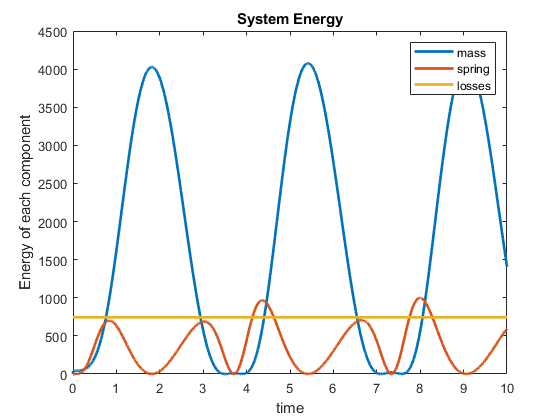

figure(2)
plot(T,EM_X,LineWidth=2); hold on;
plot(T,EK_X,LineWidth=2); hold on;
plot(T,ER_X.*ones(size(EM_X)),LineWidth=2);
ylabel('Energy of each component')
xlabel('time')
legend('mass','spring','losses')
title('System Energy')
hold off

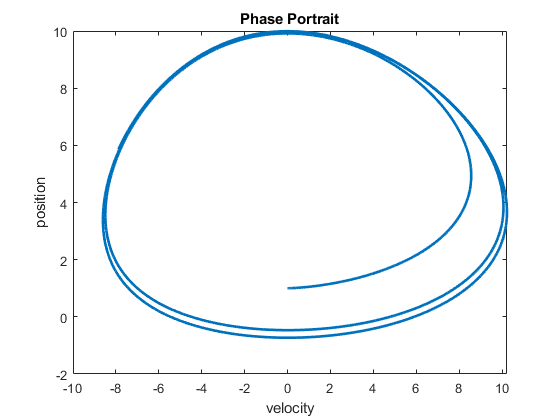

% PM = diff(EM_PHS)./diff(T);
% PK = diff(EK_phs)./diff(T);
% PR = b*diff(Vsquare_phs)./diff(T);
% figure(3)
% plot(T(2:end),PM,LineWidth=2); hold on;
% plot(T(2:end),PK,LineWidth=2); hold on;
% plot(T(2:end),PR,LineWidth=2);
% ylabel('Power states')
% xlabel('time')
% legend('Pm','Pk','Pr')
% title('Power dynamics')
% hold off

figure(4)
plot(X(2,:),X(1,:),LineWidth=2);
ylabel('position')
xlabel('velocity')
title('Phase Portrait')